# **META 2**

10. Carregue a estrutura de dados guardada no último ponto da meta anterior.

dados = load("dados.mat").dados;

tabela = struct2table(dados); 
disp(tabela);

          diretorio            nomeFicheiro      participante    digito    repeticao         sinal          taxaAmostragem    taxaCruzamentoZeros    energiaTotal    amplitudeMaxima    razaoAmplitude    desvioPadrao
    ______________________    _______________    ____________    ______    _________    ________________    ______________    ___________________    ____________    _______________    ______________    ____________

    {'audios\0_33_0.wav' }    {'0_33_0.wav' }       {'33'}         0           0        {38400×1 double}        48000               0.016523            26155    

11. Para cada sinal obtido após o pré-processamento, determine os coeficientes da série complexa de Fourier e guarde na estrutura de dados do ponto anterior.

for i=1:length(dados)
    sinal=dados(i).sinal;
    dados(i).('coeficientesFourier') = fft(sinal);
end

tabela = struct2table(dados); 
disp(tabela);

          diretorio            nomeFicheiro      participante    digito    repeticao         sinal          taxaAmostragem    taxaCruzamentoZeros    energiaTotal    amplitudeMaxima    razaoAmplitude    desvioPadrao    coeficientesFourier
    ______________________    _______________    ____________    ______    _________    ________________    ______________    ___________________    ____________    _______________    ______________    ____________    ___________________

    {'audios\0_33_0.wav' }    {'0_33_0.wav' }       {'33'}         0           0 

12. Calcule para cada dígito, o espectro de amplitude mediano, normalizado pelo número de amostras (i.e., equivalente ao módulo dos coeficientes da série complexa de Fourier), e somente para frequências positivas. Calcule também o primeiro quartil (25%) e terceiro quartil (75%). A Figura 4 mostra um exemplo. Compare os gráficos obtidos.

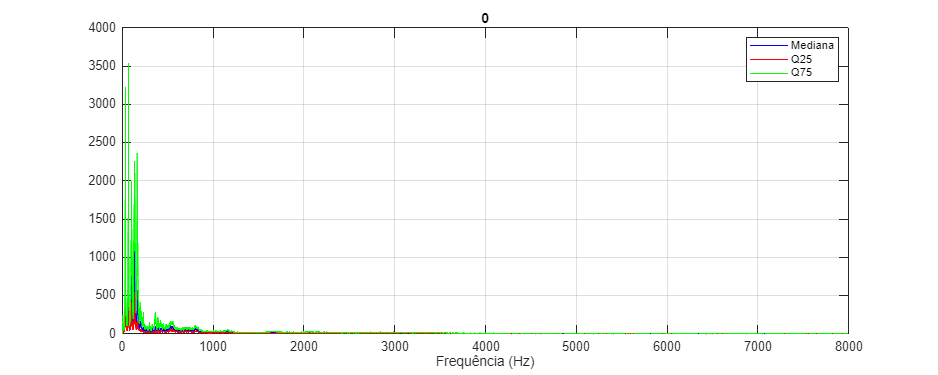

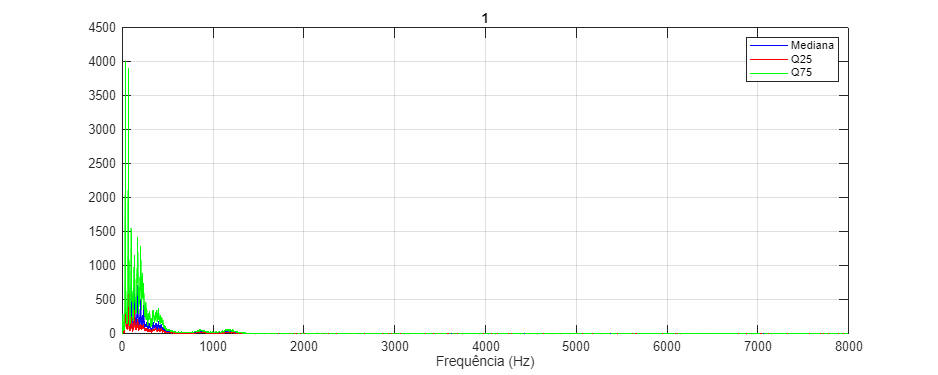

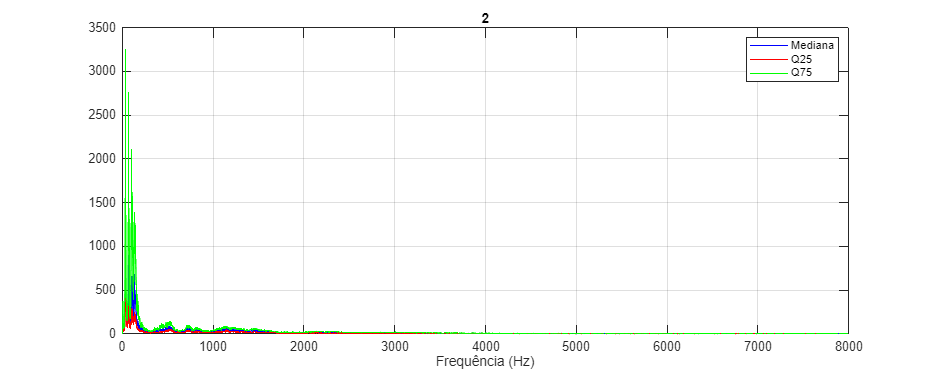

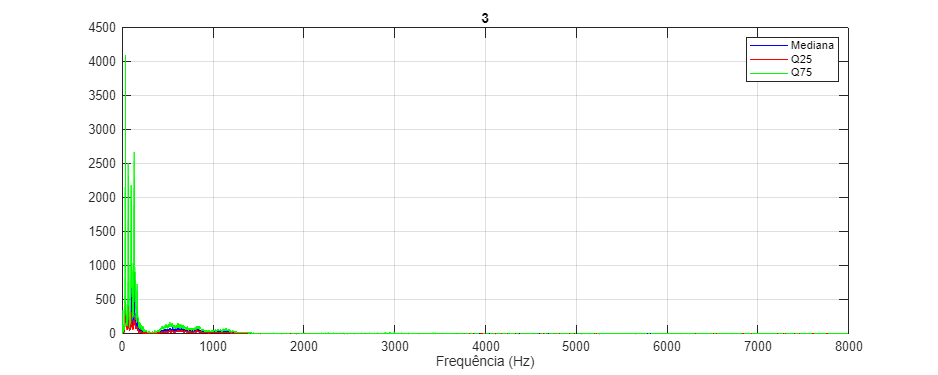

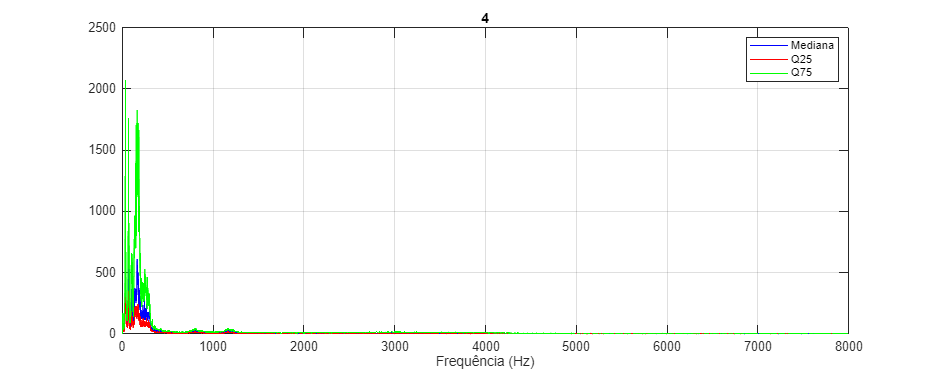

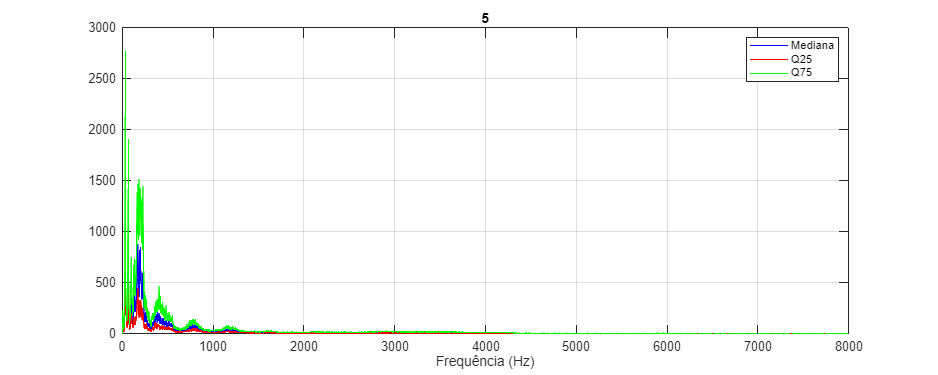

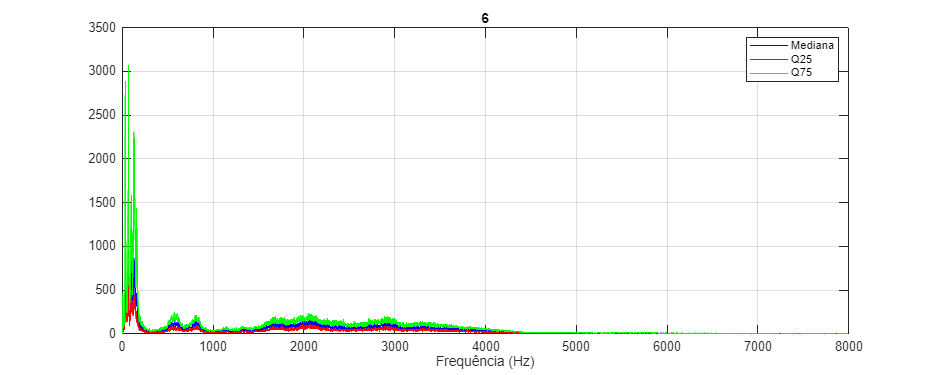

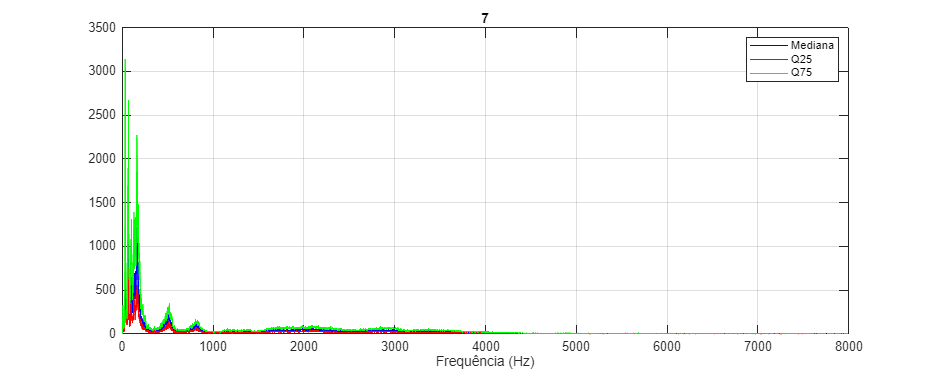


for digito = 0:9
    indices = find([dados.digito] == digito);
    espectro = [];
    
    for i = indices
        sinal = dados(i).coeficientesFourier; 
        N = length(sinal);
        
        % Normalizar o espectro pelo número de amostras
        
        amplitudeFrequencias = abs(sinal);
        
        % Selecionar somente as frequências positivas:

        amplitudeFrequencias = amplitudeFrequencias(1:N/2);

        dados(i).('amplitudeFrequencias') = amplitudeFrequencias;

        espectro = [espectro; amplitudeFrequencias(:)'];
    end
    
    % Cálculo da mediana, Q25 e Q75 para cada frequência:
    mediana = median(espectro, 1);
    q1 = quantile(espectro, 0.25, 1);
    q3 = quantile(espectro, 0.75, 1);
    
    % Vetor de frequências para o eixo x:
    numFrequencias = size(espectro,2);
    vetorFrequencias = linspace(0, 8000, numFrequencias);
    
    % Plot do espectro para o dígito atual:
    figure('Position', [100, 100, 1000, 400]);
    plot(vetorFrequencias, mediana, 'b'); hold on;
    plot(vetorFrequencias, q1, 'r');
    plot(vetorFrequencias, q3, 'g');
    title(num2str(digito));
    xlabel('Frequência (Hz)');
    legend('Mediana', 'Q25', 'Q75');
    grid on;
end

13. Identifique e implemente o cálculo de possíveis características espectrais que permitam a diferenciação entre dígitos como: máximos espectrais (posição e amplitude), médias espectrais,

spectral edge frequency, etc. Deverá efetuar o cálculo para cada áudio de pelo menos 5 características espectrais e atualizar a sua estrutura de dados.

for i = 1:length(dados)
    sinal = dados(i).sinal;
    taxaAmostragem = dados(i).taxaAmostragem; % Certifique-se de que esta variável existe
    amplitudeFrequencias = dados(i).amplitudeFrequencias;

    % Cálculo de métricas espectrais
    dados(i).('maxEspetraisAmplitudes') = max(amplitudeFrequencias);
    dados(i).('maxEspetraisPosicao') = find(amplitudeFrequencias == max(amplitudeFrequencias), 1, 'first');
    dados(i).('mediaAmplitudesFrequencias') = median(amplitudeFrequencias);

    % Parâmetros da FFT
    N = length(dados(i).coeficientesFourier); % Número de pontos na FFT
    Fv = linspace(0, taxaAmostragem/2, N/2+1); % Vetor de frequências (apenas metade positiva)
    Fouriers = abs(dados(i).coeficientesFourier(1:N/2+1)); % Apenas parte positiva do espectro

    % Integração numérica do espectro (Cumulative Sum)
    IntSpectrum = cumtrapz(Fv, Fouriers); 

    % Encontrar a frequência SEF (95% da energia total)
    SEF_threshold = 0.95 * IntSpectrum(end); % 95% da energia acumulada
    SEF = interp1(IntSpectrum, Fv, SEF_threshold, 'linear');

    % Armazena o SEF no struct
    dados(i).('SEF') = SEF;

    % Cálculo da entropia espectral (Certifique-se de que a função spectralEntropy existe)
    %entropiaEspectral = spectralEntropy(amplitudeFrequencias, taxaAmostragem);
    %dados(i).('entropiaEspectral') = entropiaEspectral;
end

% Converter estrutura para tabela para visualização
tabela = struct2table(dados);
disp(tabela);

          diretorio            nomeFicheiro      participante    digito    repeticao         sinal          taxaAmostragem    taxaCruzamentoZeros    energiaTotal    amplitudeMaxima    razaoAmplitude    desvioPadrao    coeficientesFourier    amplitudeFrequencias    maxEspetraisAmplitudes    maxEspetraisPosicao    mediaAmplitudesFrequencias     SEF  
    ______________________    _______________    ____________    ______    _________    ________________    ______________    ___________________    ____________    _______________</

14. Recorrendo à representação gráfica das características espectrais extraídas no ponto anterior, identifique as três características que permitem uma melhor discriminação dos dígitos. Para isto

pode utilizar boxplots, gráficos 2D, 3D, etc. Indique as características escolhidas.

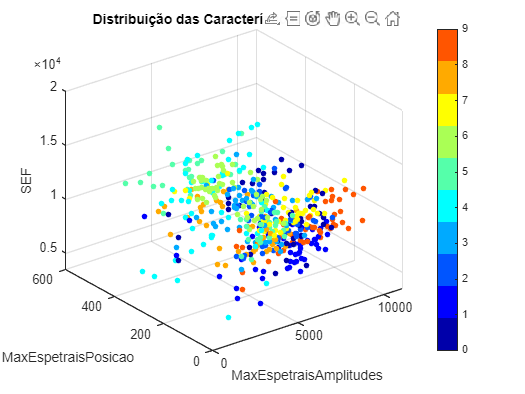


% Inicializar as caracteristicas a cruzar...
sinais = [dados.sinal];
valores1 = [dados.maxEspetraisAmplitudes];
valores2 = [dados.maxEspetraisPosicao];
valores3 = [dados.SEF];
digitos = [dados.digito];

figure;
scatter3(valores1, valores2, valores3, 20, digitos, 'filled');  
xlabel('MaxEspetraisAmplitudes');
ylabel('MaxEspetraisPosicao');
zlabel('SEF');
grid on;
title('Distribuição das Características Espectrais');

colormap(jet(10));  
clim([0 9]); 
cor = colorbar;
cor.Ticks = 0:9;  
cor.TickLabels = {'0','1','2','3','4','5','6','7','8','9'};

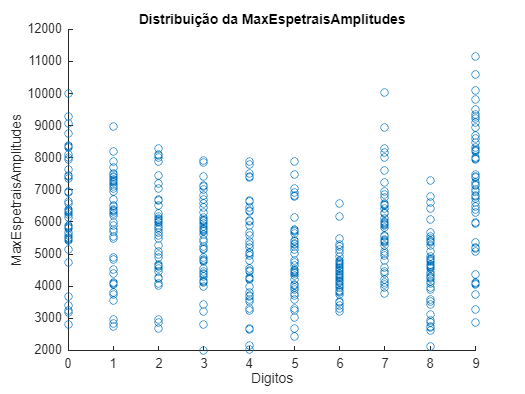

scatter(digitos,valores1,'o');
xlabel('Digitos');
ylabel('MaxEspetraisAmplitudes');
title('Distribuição da MaxEspetraisAmplitudes');

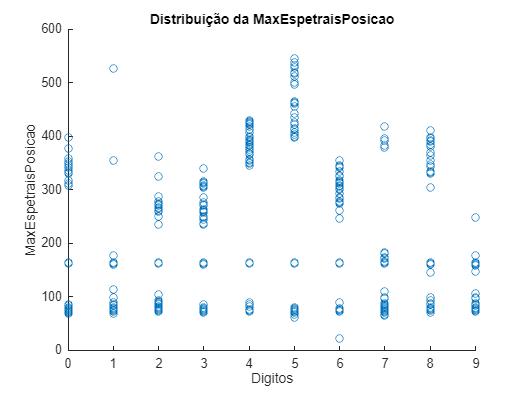

scatter(digitos,valores2,'o');
xlabel('Digitos');
ylabel('MaxEspetraisPosicao');
title('Distribuição da MaxEspetraisPosicao');

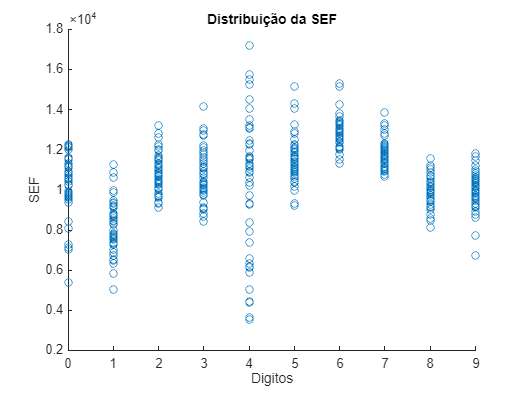

scatter(digitos,valores3,'o');
xlabel('Digitos');
ylabel('SEF');
title('Distribuição da SEF');

15. Atualize o ficheiro “.mat” carregado no início da meta com a estrutura de dados atualizada.

save('dados.mat',"dados")